Compute NHTD

clear;
clf;
currentDir = pwd;
idx = strfind(currentDir, 'ITPC');
if isempty(idx)
    error('Run this inside the ITPC folder');
end
rootFolder = currentDir(1:idx + length('ITPC') - 1);
addpath(genpath(fullfile(rootFolder, '..')));
dataPath = fullfile(rootFolder, 'Tutorialdataset2');

files = dir(fullfile(dataPath, '*.mat'));
allData = cell(numel(files),1);


for k = 1:numel(files)
    % Remove .mat extension to use as a field name
    [~, fileName] = fileparts(files(k).name);
    % Load all variables from the file
    allData{k} = load(fullfile(dataPath, files(k).name));
end

% condition x subject x channel x frequency x time 
%A = zeros(2,14,64,61,72); 

% frequency x time x channel x subject x condition
A = zeros(61,72,64,14,2); 
for k = 1:numel(files)
    % Remove .mat extension to use as a field name
    [~, fileName] = fileparts(files(k).name);
    % Load all variables from the file
    slice = load(fullfile(dataPath, files(k).name));
    if (k >=1 && k<=14)
        A(:,:,:,k,1) = abs(permute(slice.WT,[2,3,1])); %take modulus
    else 
        A(:,:,:,k-14,2) = abs(permute(slice.WT,[2,3,1])); 
    end
end

% HT approximation of tensor A
opts.max_rank = 60;
tic
A_ht = truncate(A,opts); 
toc

Elapsed time is 7.924048 seconds.


tic
%Compute NHTD X of A
selected_rank = 15;
r = selected_rank*ones(1,2*ndims(A_ht)-1); 
X = nhtd_mu(A_ht,'rank',r,'print',false); 
toc

Elapsed time is 94.639634 seconds.


% Explained Variance of A_ht
exp_var = 1 - norm(full(A_ht) - A, 'fro').^2/norm(A,'fro').^2

exp_var = 0.9669

exp_var_X = 1- norm(full(X) - A,'fro').^2/norm(A,'fro').^2

exp_var_X = 0.8608

Compute contributions for features

G = core_ten(X); 
cns = contributions(G); 
sorted = cell(ndims(X),1); 
idx_sorted = cell(ndims(X),1); 
for i = 1:ndims(X)
    [sorted{i},idx_sorted{i}] = sort(cns{i},'descend');
end  
G = G(idx_sorted{1},idx_sorted{2}, ...
    idx_sorted{3},idx_sorted{4},idx_sorted{5}); 


Plot frames

%Plot frames
U = X.U; 
sp_sz = [3,5]; %manually adjust

Plot frequency features

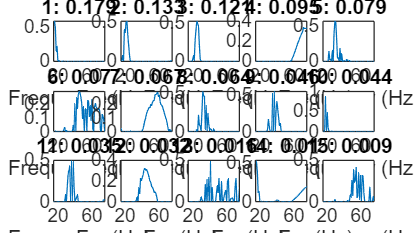

U1 = U{X.dim2ind(1)}; 
plot_frames(U1(:,idx_sorted{1}),'line', ...
    'sp_sz', sp_sz, ...
    'x',15:75, ...
    'xlim',[15,75], ...
    'xlabel','Frequency (Hz)', ...
    'subtitles', string(1:size(U1,2))+": " ...
    +string(round(sorted{1},3))'); 
exportgraphics(gcf, 'freq_comps.pdf', 'ContentType', 'vector')

Plot time features

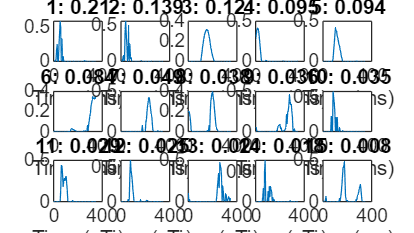

U2 = U{X.dim2ind(2)};
plot_frames(U2(:,idx_sorted{2}),'line', ...
    'sp_sz',sp_sz, ...
    'x',linspace(0,346.68,72), ...
    'xlabel','Time (ms)', ...
    'subtitles', string(1:size(U2,2))+": " ...
    +string(round(sorted{2},3))'); 
exportgraphics(gcf, 'time_comps.pdf', 'ContentType', 'vector')

Plot channel features

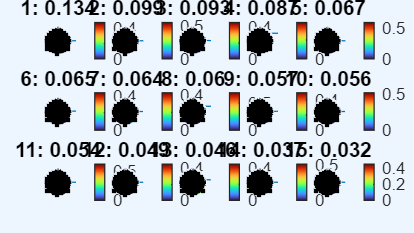

% Plot topography
file = allData{1}; 
chanlocs = file.chanlocs; 
srs = string(round(sorted{3},3))'; 
U3 = U{X.dim2ind(3)}; 
for i = 1:size(U3,2)
    subplot(sp_sz(1),sp_sz(2),i);
    itpc_map = U3(:,idx_sorted{3}(i));
    topoplot(itpc_map, chanlocs, ...
        'style','map',...
        'maplimits',[0 max(itpc_map(:))], ...
        'conv','on');
    colorbar;
    title(num2str(i)+": "+ srs(i)); 
    axis off
    ax = gca;
    ax.Position = ax.OuterPosition;   
    ax.LooseInset = [0 0 0 0];        
end 
width = 8;
ratio = 16/9;
height = width / ratio;
set(gcf, 'Units', 'Inches', 'Position', [1 1 width height]);
exportgraphics(gcf, 'channel_comps.pdf', 'ContentType', 'vector')

Headplot: using existing XYZ coordinates
Loaded mesh file mheadnew.mat
Setting up splining matrix.
Calculating splining matrix...
Computing electrode locations on head...
Computing 6067 vertices. Should take a while (see wait bar)
            but does not have to be done again for this montage...
Saving (3144k) file splinefile.spl


file = allData{1}; 
chanlocs = file.chanlocs; 
srs = string(round(sorted{3},3))'; 
headplot('setup', chanlocs, 'splinefile.spl');

U3 = U{X.dim2ind(3)}; 
for i = 1:size(U3,2)
    subplot(sp_sz(1),sp_sz(2),i);
    itpc_map = U3(:,idx_sorted{3}(i));
    headplot(itpc_map, 'splinefile.spl', ...
    'electrodes','off', ...
    'maplimits',[0 max(itpc_map)]);
    title(num2str(i)+": "+ srs(i)); 
end 

Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat
Loaded mesh file mheadnew.mat


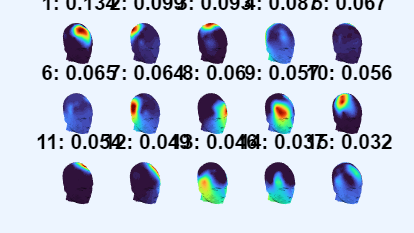

width = 6;
ratio = 16/9;
height = width / ratio;
set(gcf, 'Units', 'Inches', 'Position', [1 1 width height]);

fig = openfig('3dheads.fig','invisible');
set(fig,'Renderer','painters');   % force vector renderer
exportgraphics(fig, '3dheads.pdf', 'ContentType','vector');
close(fig);

Plot subject features

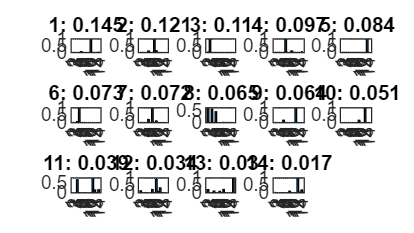

U4 = U{X.dim2ind(4)};
plot_frames(U4(:,idx_sorted{4}),'bar', ...
    'width',8,...
    'sp_sz', sp_sz, ...
    'subtitles', string(1:size(U4,2))+": " ...
    +string(round(sorted{4},3))'); 
exportgraphics(gcf, 'subject_comps.pdf', 'ContentType', 'vector')

Plot condition features

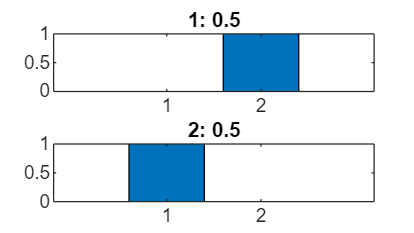

U5 = U{X.dim2ind(5)};
plot_frames(U5(:,idx_sorted{5}),'bar', ...
    'width',4,...
    'subtitles', string(1:size(U5,2))+": " ...
    +string(round(sorted{5},3))'); 
exportgraphics(gcf, 'condition_comps.pdf', 'ContentType', 'vector')

Display joint rate indices between lowest level features

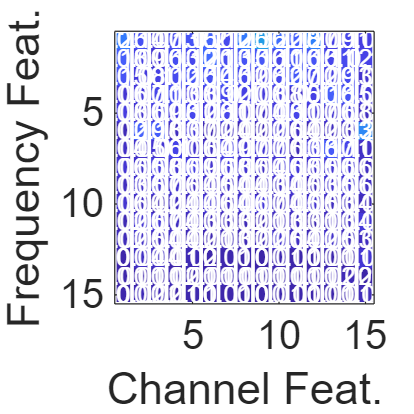

plot_mat(jr_idx(G,[1,3]),'FontSize',10);
xlabel('Channel Feat.'); ylabel('Frequency Feat.');
clim([0,1])
exportgraphics(gcf, 'freq_channel_jr_mat.pdf', 'ContentType', 'vector')

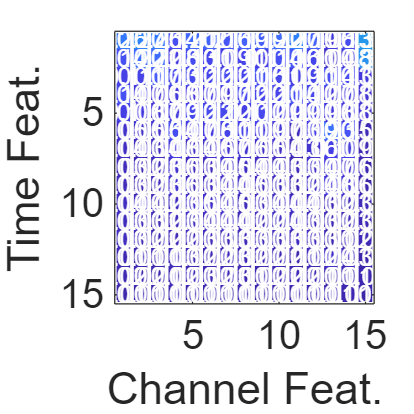


plot_mat(jr_idx(G,[2,3]),'FontSize',10);
xlabel('Channel Feat.'); ylabel('Time Feat.');
clim([0,1])
exportgraphics(gcf, 'time_channel_jr_mat.pdf', 'ContentType', 'vector')

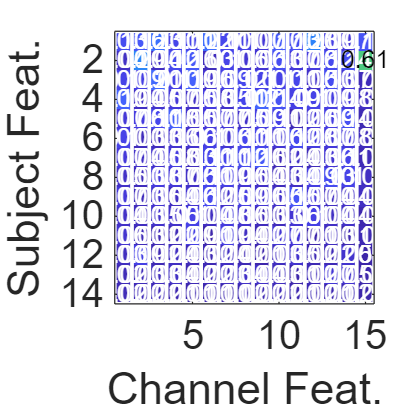


plot_mat(jr_idx(G,[4,3]),'FontSize',10);
xlabel('Channel Feat.'); ylabel('Subject Feat.'); 
clim([0,1])
exportgraphics(gcf, 'subject_channel_jr_mat.pdf', 'ContentType', 'vector')

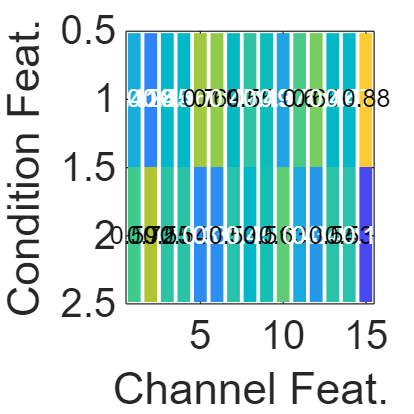


plot_mat(jr_idx(G,[5,3]),'FontSize',10, 'width',6);
xlabel('Channel Feat.'); ylabel('Condition Feat.'); 
clim([0,1])
exportgraphics(gcf, 'condition_channel_jr_mat.pdf', 'ContentType', 'vector')


% labels = {'Freq. Feat.', 'Time Feat.', ...
%     'Channel Feat.', 'Subject Feat.', 'Condition Feat.'}; 
% plot_mats(G,'labels', labels,'FontSize',4, ...
%     'threshold',0.25,'climits',[0,0.5]);
% saveas(gcf,'jr_idx_plot.png')

Display tables of clusters between lower level features

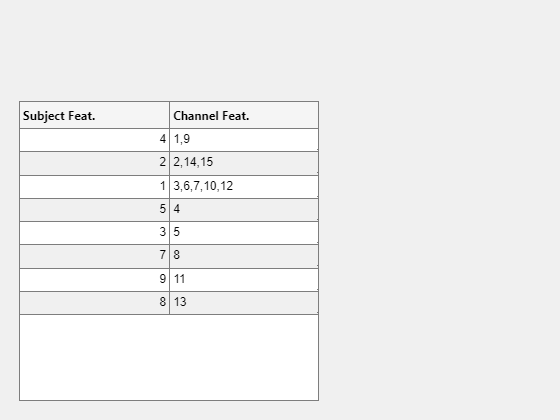

labels = {'Frequency Feat.', 'Time Feat.', ...
    'Channel Feat.','Subject Feat.','Condition Feat.'}; 
tables(G,labels,3,4);

Construct Y

t_left = X.dim2ind(1);
t_right = X.dim2ind(2); 

Y = truncate_leaf_pair(X, t_left,t_right);  

Recompute contributions given G_Y and reorder modes of G_Y based on these contributions. 

G_Y = core_ten(Y);
cns_Y = contributions(G_Y); 
sorted_Y = cell(ndims(Y),1); 
idx_sorted_Y = cell(ndims(Y),1); 
for i = 1:ndims(Y)
    [sorted_Y{i},idx_sorted_Y{i}] = sort(cns_Y{i},'descend');
end  
G_Y = G_Y(idx_sorted_Y{1},idx_sorted{3}, ...
    idx_sorted{4},idx_sorted{5}); 

Joint rate index between freq-time and channel features

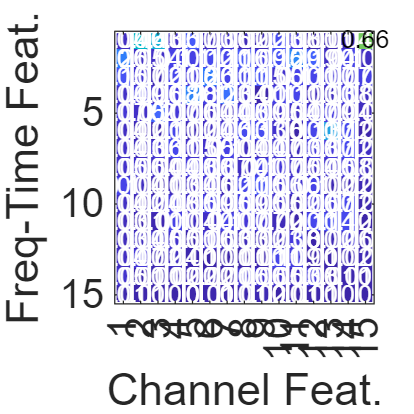

plot_mat(jr_idx(G_Y,[1,2]),'FontSize',10)
xlabel('Channel Feat.'); ylabel('Freq-Time Feat.'); 
xticks(1:size(G_Y,2)); 
clim([0,1]);
exportgraphics(gcf, 'freq-time_channel_jr_idx.pdf', 'ContentType', 'vector')

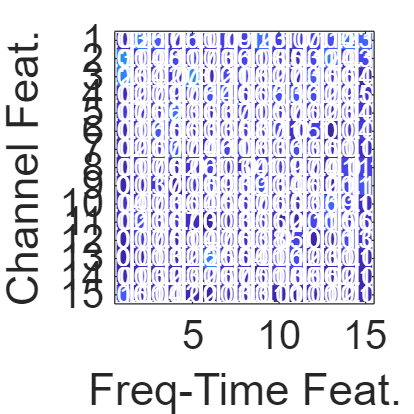


plot_mat(jr_idx(G_Y,[2,1]),'FontSize',10)
xlabel('Freq-Time Feat.'); ylabel('Channel Feat.'); 
yticks(1:size(G_Y,2)); 
clim([0,1]);
exportgraphics(gcf, 'channel_freq-time_jr_idx.pdf', 'ContentType', 'vector')

Plot freq-time features

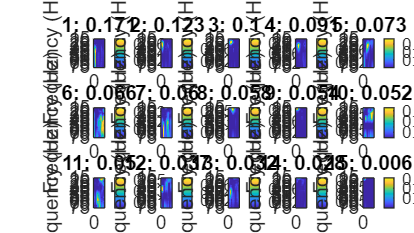

U_ft = frameU(2,X);  %ft: freq-time
U_ft = U_ft(:,idx_sorted_Y{1}); % order based on contributions 
U_ft = reshape(U_ft,size(X,1),size(X,2),[]);
srs_ft = string(round(sorted_Y{1},3))'; 

%Need to fix axis labels
plot_frames(U_ft,'2d', ...
    'width',8,...
    'cols', linspace(0,346.68,72), ...
    'rows', 15:75, ...
    'yticks',15:5:75, ...
    'xlabel','Time (ms)', ...
    'ylabel','Frequency (Hz)', ...
    'sp_sz', sp_sz, ...
    'subtitles', string(1:size(U_ft,3))+": "+srs_ft); 
exportgraphics(gcf, 'freq-time_comps.pdf', 'ContentType', 'vector')

Display tables of clusters between freq-time and channel features

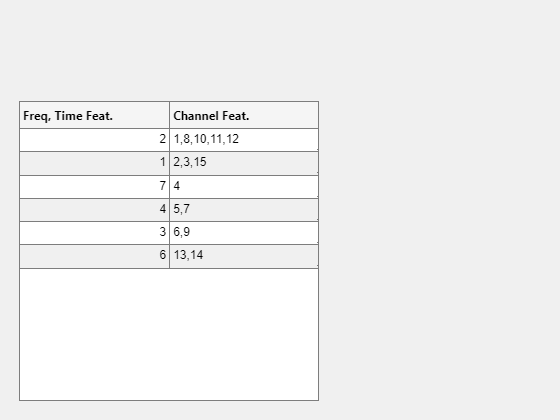

labels = {'Freq, Time Feat.','Channel Feat.','Subject Feat.','Condition Feat.'}; 
tables(G_Y,labels,2,1)